## Read the audio signal

% assumptions made on the signals:
% 1- they have same sampling rate
% 2- they are less than 10 seconds
% 3- they are mono not stereo
speechSignalFileName = 'Comm_Signal';
[signal1, Fs1] = audioread([speechSignalFileName '_1.wav']);
[signal2, Fs2] = audioread([speechSignalFileName '_2.wav']);
[signal3, Fs3] = audioread([speechSignalFileName '_3.wav']);

## Edit the signals to be with equal length

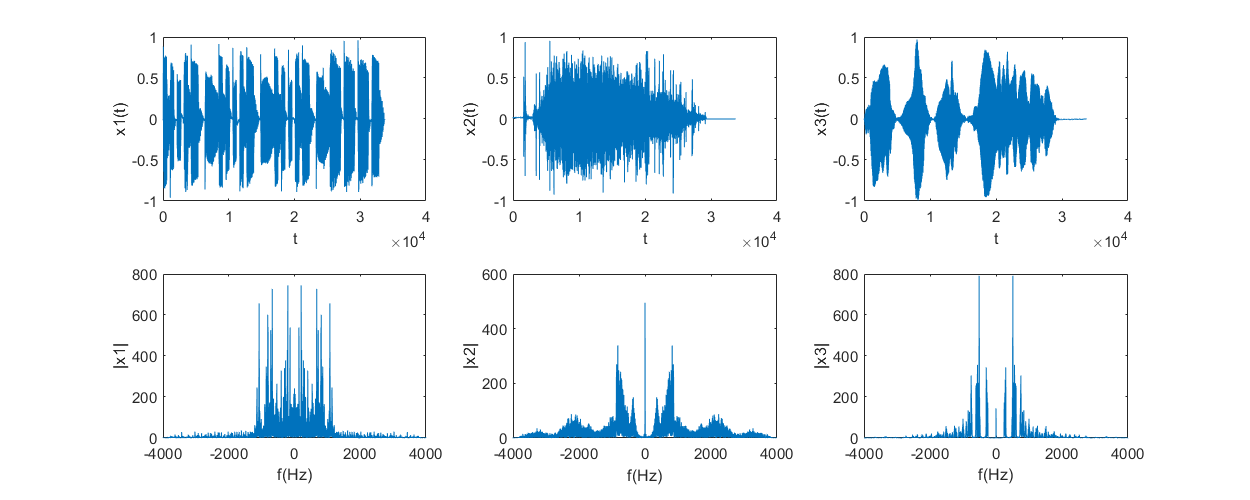

% padding1 = 0;
% padding2 = 0;
% padding3 = 0;
maxSamples = max(max(length(signal2), length(signal3)), length(signal1));

if length(signal1) ~= maxSamples
    padding1 = maxSamples - length(signal1);
    signal1 = padarray(signal1, maxSamples - length(signal1), 0, "post");
end

if length(signal2) ~= maxSamples
    padding2 = maxSamples - length(signal2);
    signal2 = padarray(signal2, maxSamples - length(signal2), 0, "post");
end

if length(signal3) ~= maxSamples
    padding3 = maxSamples - length(signal3);
    signal3 = padarray(signal3, maxSamples - length(signal3), 0, "post");
end

displaySignals(signal1, signal2, signal3, Fs1, "After extending to same length");

## Up sampling the signals to be able to extract the signal in demodulation

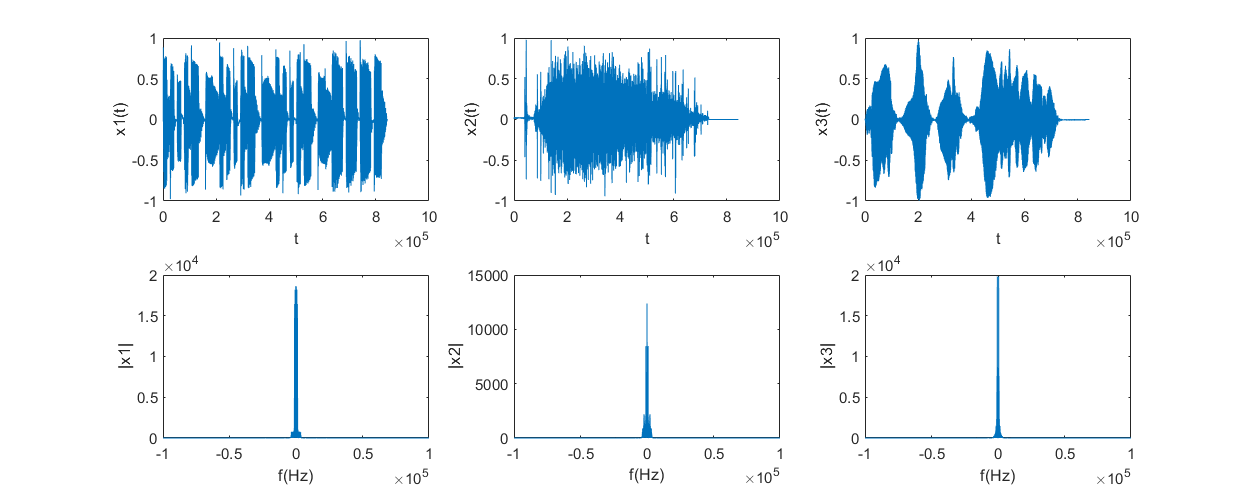

upSamplingRate = 25;

signal1 = resample(signal1, upSamplingRate, 1);
signal2 = resample(signal2, upSamplingRate, 1);
signal3 = resample(signal3, upSamplingRate, 1);
%to satisfy nyquist ratio Fs > 2*Fm
Fs1 = Fs1 * upSamplingRate;
Fs2 = Fs2 * upSamplingRate;
Fs3 = Fs3 * upSamplingRate;

displaySignals(signal1, signal2, signal3, Fs1, "After upsampling");

## Perform modulation

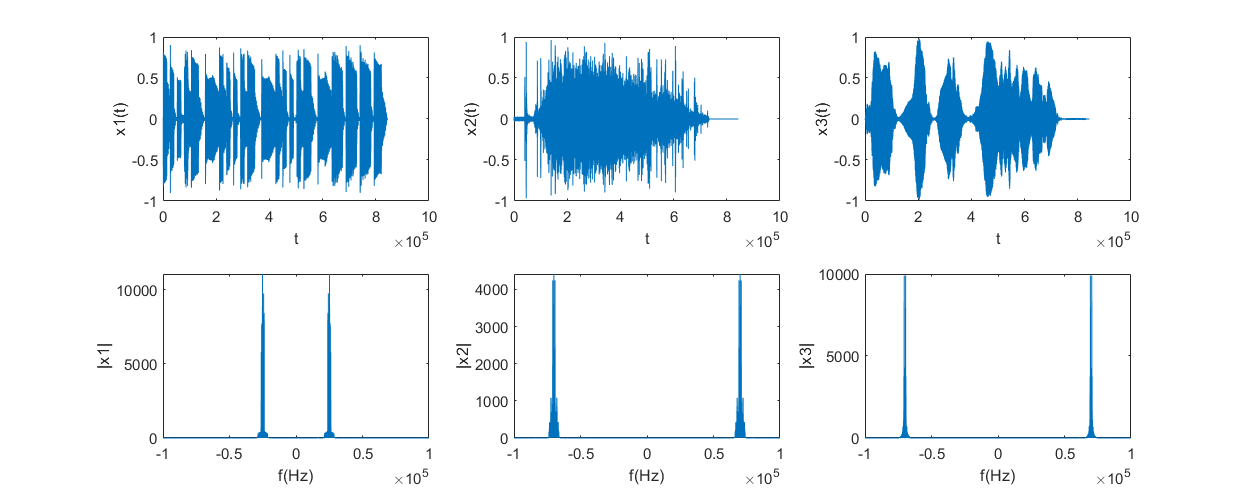

% modulating signals
duration = length(signal1) ./ Fs1;
t = -(duration-1/Fs1)/2 : 1/Fs1 :(duration-1/Fs1)/2;

% current Fs is 200kHz assume worst case that our sound signals take a
% bandwidth of 20KHz
fcarrier1 = 25000;
fcarrier2 = 70000;

% generate the carriers
carrier1 = cos(2 * pi * fcarrier1 * t);
carrier2 = cos(2 * pi * fcarrier2 * t);
carrier3 = sin(2 * pi * fcarrier2 * t);

% generate the modulated signals
s1 = signal1' .* carrier1;
s2 = signal2' .* carrier2;
s3 = signal3' .* carrier3;

displaySignals(s1, s2, s3, Fs1, "Signals after modulating the carriers");

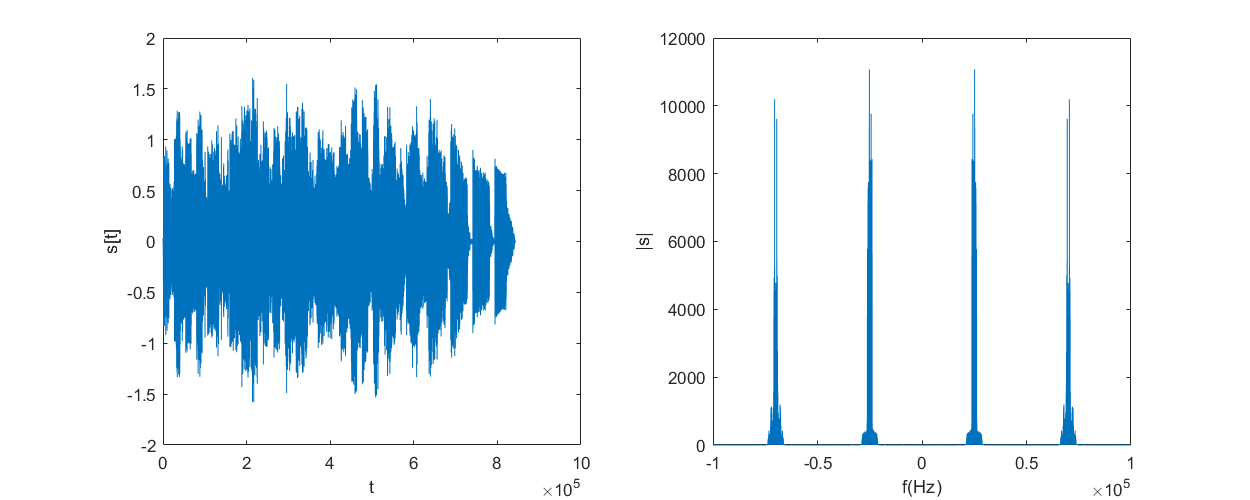


s = s1 + s2 + s3;

displaySignal(s, Fs1, "Modulated Signal");

## Perform demodulation with phase shifts

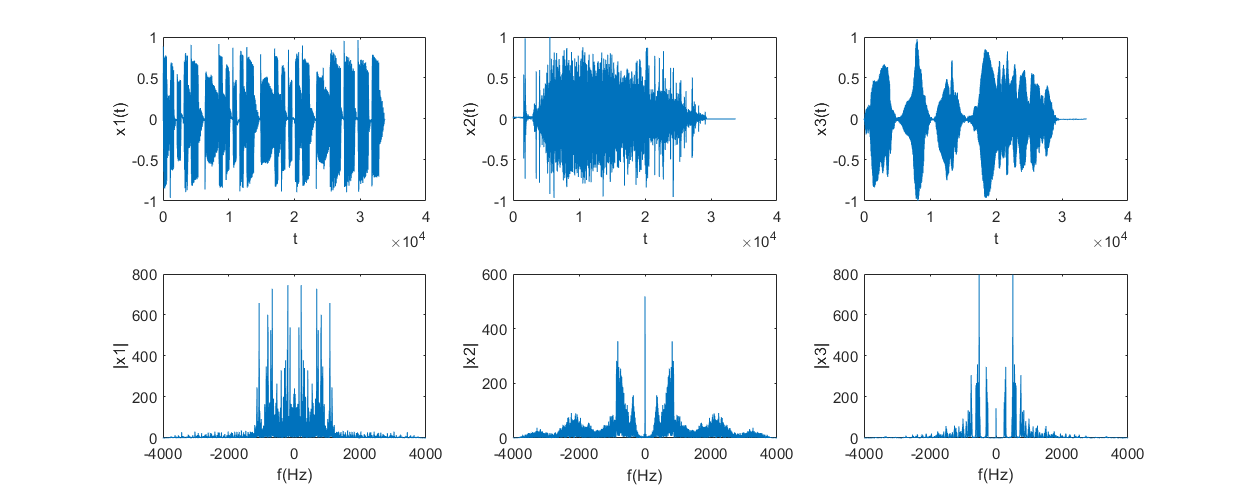

% synchronous demodulation
demodulateWithPhaseShift(s, 0, Fs1, upSamplingRate, fcarrier1, fcarrier2, speechSignalFileName);

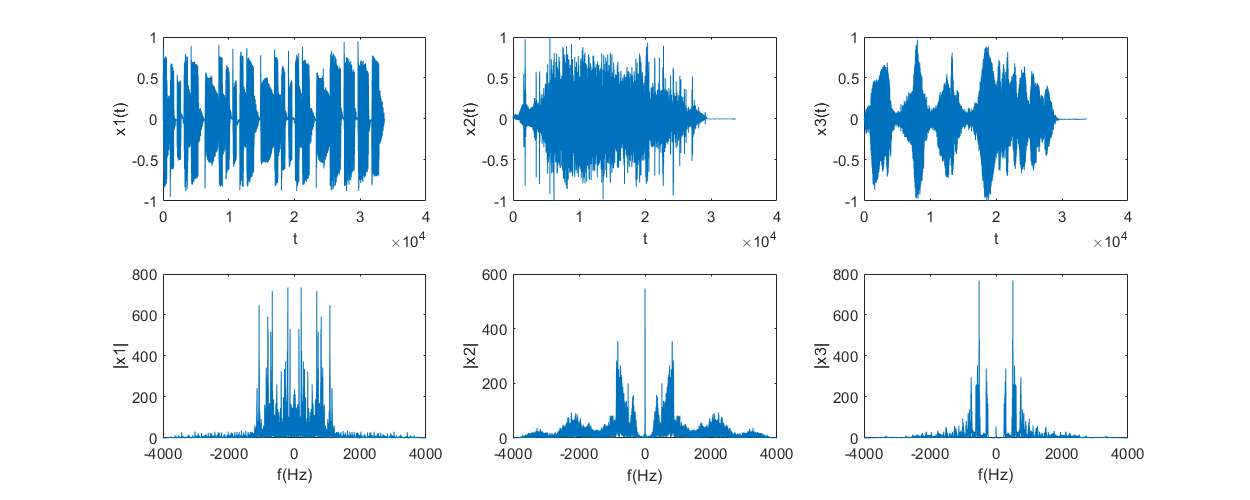


% demodulation with phase shift = 10 degrees
demodulateWithPhaseShift(s, 10, Fs1, upSamplingRate, fcarrier1, fcarrier2, speechSignalFileName);

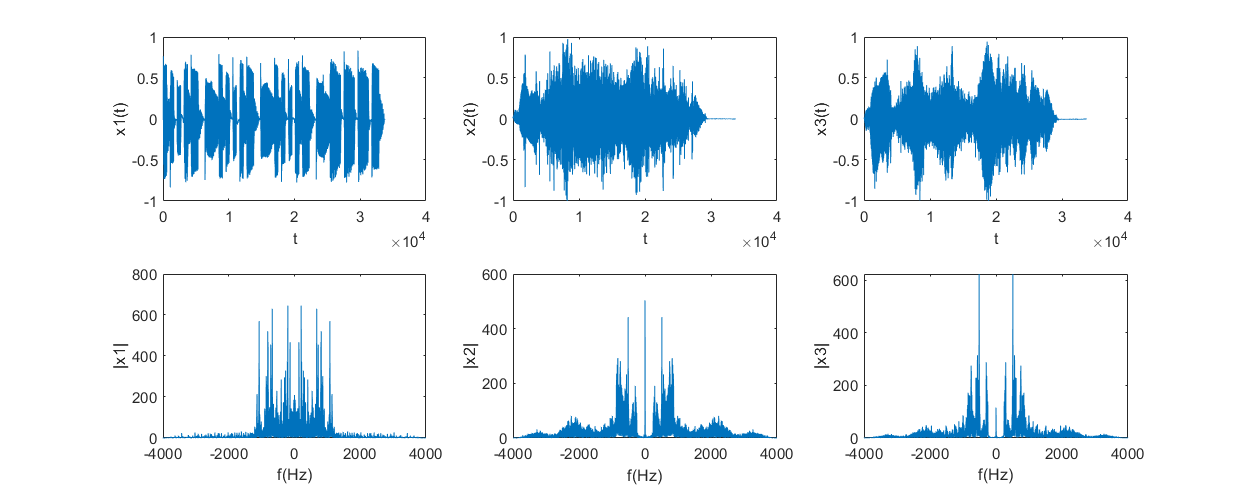


% demodulation with phase shift = 30 degrees
demodulateWithPhaseShift(s, 30, Fs1, upSamplingRate, fcarrier1, fcarrier2, speechSignalFileName);

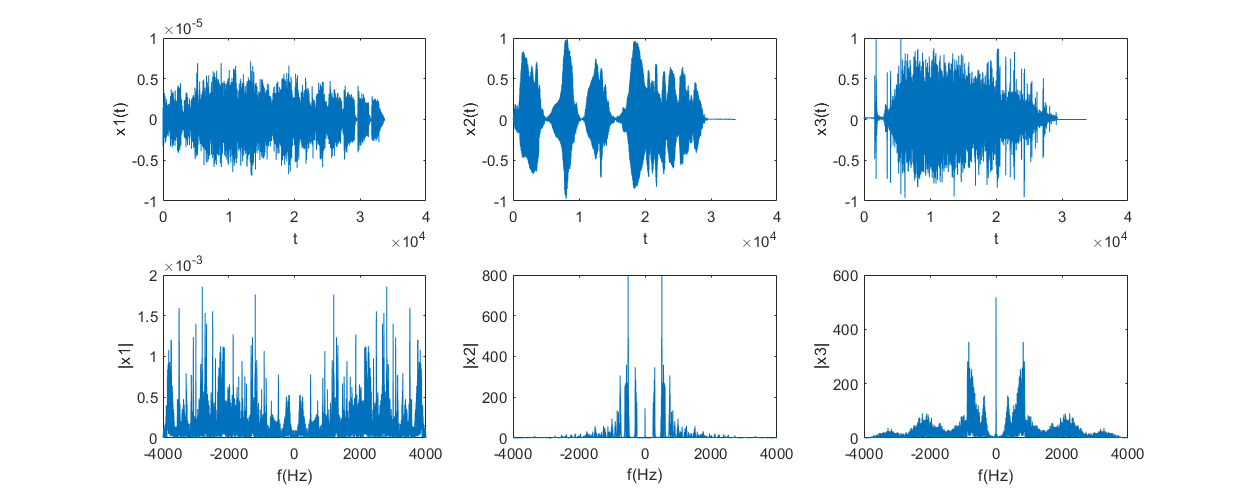


% demodulation with phase shift = 90 degrees
demodulateWithPhaseShift(s, 90, Fs1, upSamplingRate, fcarrier1, fcarrier2, speechSignalFileName);

## Perform demodulation with frequency shift

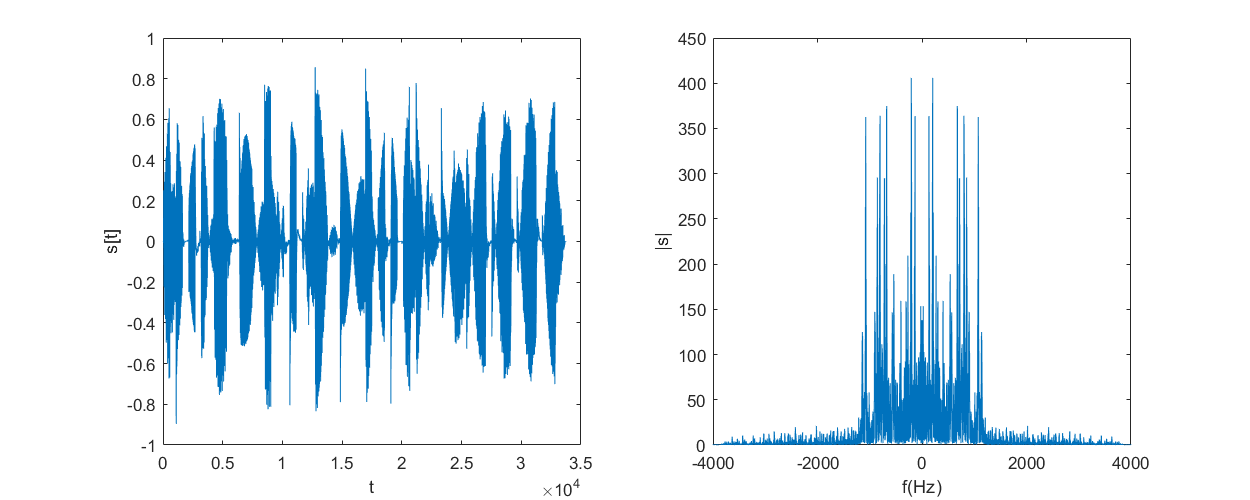

% demodulation with frequency shift = 2 Hz
demodulateWithFreqShift(s, 2, Fs1, upSamplingRate, fcarrier1, speechSignalFileName)

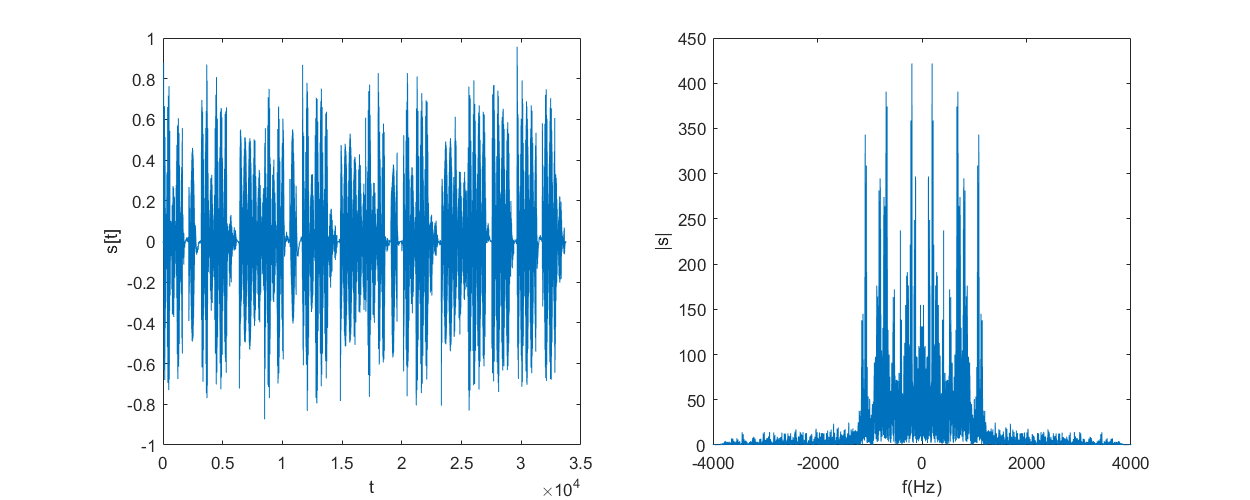


% demodulation with frequency shift = 10 Hz
demodulateWithFreqShift(s, 10, Fs1, upSamplingRate, fcarrier1, speechSignalFileName)

## **Functions**

function [x, y] = audioMagnitudeSpectrum(signal, Fs)
    x = (-Fs/2 : Fs/length(signal) : Fs/2 - Fs/length(signal));
    y = abs(fftshift(fft(signal)));
end

% Function used to plot one signal in the time domain
% and the magnitude spectrum
function displaySignal(signal, Fs, figureTitle)
    figure('name', figureTitle);
    set(gcf,'position', [100 100 1000 400]);
    
    subplot(1,2,1);
    plot(signal); ylabel("s[t]"); xlabel("t");
    
    subplot(1,2,2);
    [x, y] = audioMagnitudeSpectrum(signal, Fs);
    plot(x, y); ylabel("|s|"); xlabel("f(Hz)");
end

% Function used to plot three signals in the time domain
% and the magnitude spectrum
function displaySignals(signal1, signal2, signal3, Fs, figureTitle)
    figure('name', figureTitle);
    set(gcf,'position', [100 100 1000 400]);
    
    subplot(2,3,1);
    plot(signal1);
    ylabel("x1(t)"); xlabel("t");
    
    subplot(2,3,2);
    plot(signal2);
    ylabel("x2(t)"); xlabel("t");
    
    subplot(2,3,3);
    plot(signal3);
    ylabel("x3(t)"); xlabel("t");

    subplot(2,3,4);
    [x, y] = audioMagnitudeSpectrum(signal1, Fs);
    plot(x, y); ylabel("|x1|"); xlabel("f(Hz)");
    
    subplot(2,3,5);
    [x, y] = audioMagnitudeSpectrum(signal2, Fs);
    plot(x, y); ylabel("|x2|"); xlabel("f(Hz)");
    
    subplot(2,3,6);
    [x, y] = audioMagnitudeSpectrum(signal3, Fs);
    plot(x, y); ylabel("|x3|"); xlabel("f(Hz)");
end

function demodulateWithPhaseShift(signal, phaseShiftDegrees, Fs, upSamplingRate, fcarrier1, fcarrier2, speechSignalFileName)
    duration = length(signal) ./ Fs;
    t = -(duration-1/Fs)/2 : 1/Fs :(duration-1/Fs)/2;
    
    carrier1 = cos(2 * pi * fcarrier1 * t + (phaseShiftDegrees * pi / 180));
    carrier2 = cos(2 * pi * fcarrier2 * t + (phaseShiftDegrees * pi / 180));
    carrier3 = sin(2 * pi * fcarrier2 * t + (phaseShiftDegrees * pi / 180));
    
    % demodulate
    output1 = 2*(carrier1 .* signal);%darbna fe 2 34an ali bytl3 0.5x(t)
    output2 = 2*(carrier2 .* signal);
    output3 = 2*(carrier3 .* signal);
    
    % applying low pass filter
    output1 = lowpass(output1, 20000, Fs);
    output2 = lowpass(output2, 20000, Fs);
    output3 = lowpass(output3, 20000, Fs);
    
    % downsmapling the signals to the original sampling rate
    output1 = resample(output1, 1, upSamplingRate);
    output2 = resample(output2, 1, upSamplingRate);
    output3 = resample(output3, 1, upSamplingRate);
    
    %normaize
    output2 = output2/(max(abs(output2)));
    output3 = output3/(max(abs(output3)));
    
    Fs = Fs / upSamplingRate;
    displaySignals(output1, output2, output3, Fs, ['Demodulation output phase ' int2str(phaseShiftDegrees)]);
    
    % save audio files
    audiowrite([speechSignalFileName '_phase_1_' int2str(phaseShiftDegrees) '.wav'], output1, Fs);
    audiowrite([speechSignalFileName '_phase_2_' int2str(phaseShiftDegrees) '.wav'], output2, Fs);
    audiowrite([speechSignalFileName '_phase_3_' int2str(phaseShiftDegrees) '.wav'], output3, Fs);
end

function demodulateWithFreqShift(signal, freqShift, Fs, upSamplingRate, fcarrier1, speechSignalFileName)
    duration = length(signal) ./ Fs;
    t = -(duration-1/Fs)/2 : 1/Fs :(duration-1/Fs)/2;
    
    carrier1 = cos(2 * pi * (fcarrier1 + freqShift) * t);
    
    % demodulate
    output1 = 2*(carrier1 .* signal);
    
    % applying low pass filter
    output1 = lowpass(output1, 20000, Fs);
    
    % downsmapling the signals to the original sampling rate
    output1 = resample(output1, 1, upSamplingRate);
    
    Fs = Fs / upSamplingRate;
    displaySignal(output1, Fs, ['Demodulation output frequency ' int2str(freqShift)]);
    
    % save audio files
    audiowrite([speechSignalFileName '_freq_1_' int2str(freqShift) '.wav'], output1, Fs);
end